# imitate PDDFs  dc oct 23

cd ('/gs/gsfs0/shared-lab/cowburnlab/New folder1')
clearvars
close all
seq=readlines('../TraDES-2/FSFG12.faa');    % sequence of FSFG12    
seq=seq(1);  % ensure single line read
s2=char(seq);
ns=19;
for ii=1:ns:numel(s2)

disp(s2(ii:min(ii+ns,numel(s2))));
end

MNETSKPAFSFGAKSDEKKD
DGDASKPAFSFGAKPDENKA
ASATSKPAFSFGAKPEEKKD
DDNSSKPAFSFGAKSNEDKQ
QDGTAKPAFSFGAKPAEKNN
NNETSKPAFSFGAKSDEKKD
DGDASKPAFSFGAKSDEKKD
DGDASKPAFSFGAKPDENKA
ASATSKPAFSFGAKPEEKKD
DDNSSKPAFSFGAKSNEDKQ
QDGTAKPAFSFGAKPAEKNN
NNETSKPAFSFGAKSDEKKD
DGDASKPALEHHHHHH*


seq=regexprep(seq,'\*','');     % remove any terminal *
maskf=char(seq)=='F';           % find F positions; 
maskf=gpuArray(maskf);
ff=find(maskf);

dr=7;                          % value of center-center scattering 
% distance averaged for CG-CG for F-F pairs
dr2=eps;      %additional CG-CG distance
nu=0.55;        % Flory coeff for self avoiding walk 
b=zeros(max(ff),1);         % count of Center-Center 
b=gpuArray(b);
for ii=1:numel(ff)-1
    d{ii}=ff(end:-1:ii+1)-ff(ii); %#ok<SAGROW>  % distance set
    for jj=d{ii}
        b(jj)=b(jj)+1;
    end

end

H=figure;
 tiledlayout(1,3,'Padding','none');

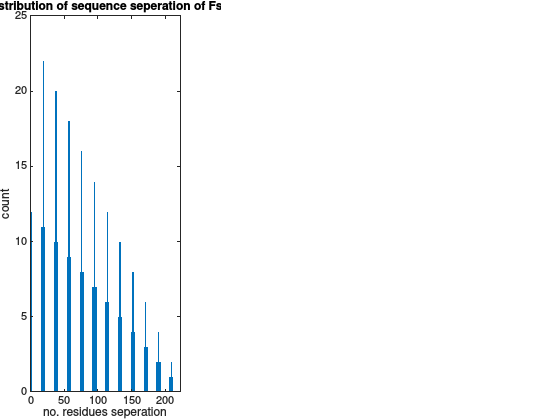

        nexttile;
bar(b,2); xlabel('no. residues seperation');
ylabel('count');
title ('distribution of sequence seperation of Fs');

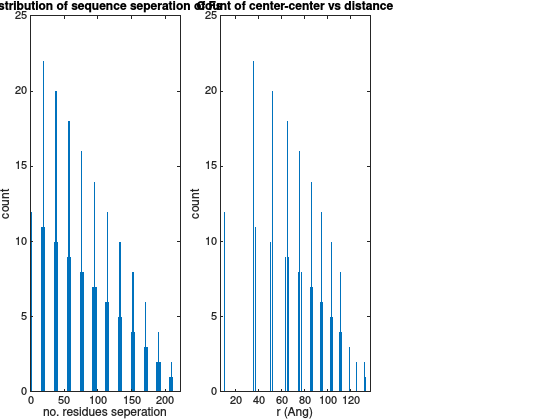

% distance distribution

x=1:numel(b);
%x=x*dr+dr2;
x=x.^nu;    % distances 
x=x*dr+dr2;
nexttile;
bar(x,b,2);
xlabel ('r (Ang)'); ylabel('count');
title('Count of center-center vs distance');

## smear

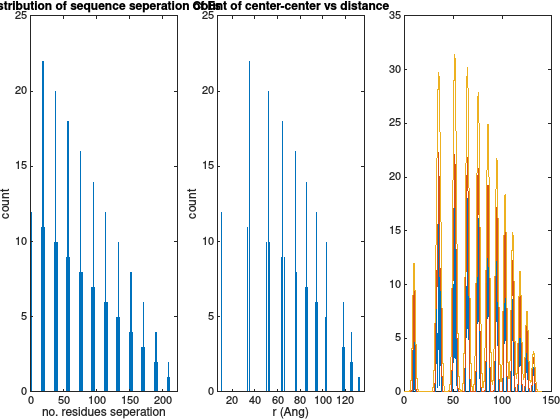

zstep=0.01;  % setup  a grid
z=1:zstep:5+max(ceil(x));

f_g=@(x,x0,s) (exp(-((x-x0)/s).^2));    %Gaussian
fb=find(logical(b));
nexttile

for s=[0.5 1  2  3 ]


    rd=f_g(x(fb)',z,s).*b(fb);
    y=sum(rd);
    plot(z,y,'DisplayName',num2str(s)); hold on;
end


xlabel('r (A)'); ylabel('Intensity'); title('Random Coil Model');
legend();
%axis([0 Inf 0 max(x)])
H.PaperOrientation='landscape';
H.PaperSize=[11 5]; 
print('sim1','-dpdf','-fillpage')